# Tarefa 1 - Linearização

### Andrei Leandro Morsch Franco

## Importante! todo código está disponível em:

[https://github.com/morschfranco/Tarefa01](https://github.com/morschfranco/Tarefa01)

Importante: o script tende a ser aprimorado ao longo das revisões (_revXX) 

Esta é a segunda revisão (Tarefa_01_Sistemas_Lineares_2022_3_Andrei_Franco_5p_rev02.mlx)

Considerando o enunciado, foram utilizadas as variáveis, parâmetros do sistema e equações de [1] e [3]

No ponto de equilíbrio, os jacobianos  não variam no tempo, o que nos permite reescrever a equação linearizada em termos de matrizes constantes. Ao longo de [2] são apresentados desdobramentos, que foram considerados para compreender melhor o MZSH.

clear;

syms cb v3 qb v3max alfa Tbmax mb cpw ab Te real;
syms cl1 v4 cb1 v4max P1 al1 ch1 v1 v1max qsi Th1 Tz1 ah1 real;
syms cz1 az1 Tp az12 real;
syms cl2 v5 cb2 v5max P2 al2 real;
syms ch2 v2 v2max ah2 real;
syms cz2 az2 real;
syms P1max P2max deltaT1max deltaT2max real; 
syms dv4dt dqbdt dv5dt dv1dt dcb1dt dv2dt dcb2dt real;
syms dTedt dTpdt real;
syms Tbss Tl1ss Th1ss Tz1ss Tl2ss Th2ss Tz2ss Tess Tpss real;
syms v1ss v2ss v3ss v4ss v5ss real;
syms Tb Tl1 Th1 Tz1 Tl2 Th2 Tz2 real;


%CMP - compressor;
%E - evaporador;
%C - condensador;
%D - difusor;
%F - ventilador;
%vi - entradas de controle (i = 1,··· ,5);
%yj - saídas a controlar (j = 1,2,3);
%SW - fornecimento de água;
%RW - retorno de água

% Conjunto de equações do modelo matemático do MZSH

% Tb - temperatura no boiler
dTbdt = 1/cb*(v3*v3max*(1-alfa*Tb/Tbmax)-mb*cpw*(Tb-Tl1)-mb*cpw*(Tb-Tl2)-ab*(Tb-Te));
% Tl1- temperatura no evaporador da zona 1
dTl1dt = 1/cl1*(-v4*v4max*(P1-1)+mb*cpw*(Tb-Tl1)-al1*(Tl1-Te));
% Th1 - temperatura no condensador da zona 1
dTh1dt = 1/ch1*(v4*v4max*P1-v1*v1max*qsi*(Th1-Tz1)-ah1*(Th1-Te));
% Tz1 - temperatura na zona 1
dTz1dt = 1/cz1*(v1*v1max*qsi*(Th1-Tz1)-az1*(Tz1-Tp)-az12*(Tz1-Tz2));
% Tl2 - temperatura no evaporador da zona 2
dTl2dt = 1/cl2*(-v5*v5max*(P2-1)+mb*cpw*(Tb-Tl2)-al2*(Tl2-Te));
% Th2 - temperatura no condensador da zona 2
dTh2dt = 1/ch2*(v5*v5max*P2-v2*v2max*qsi*(Th2-Tz2)-ah2*(Th2-Te));
% Tz2 - temperatura na zona 2
dTz2dt = 1/cz2*(v2*v2max*qsi*(Th2-Tz2)-az2*(Tz2-Tp)+az12*(Tz1-Tz2));

% De maneira complementar, são representado(a)s:
% v1 - ventilador zona 1
% v2 - ventilador zona 2
% v3 = qb - queimador do boiler
% v4 = cb1 - compressor da bomba de calor da zona 1
% v5 = cb2 - compressor da bomba de calor da zona 2
% Te - temperatura da instalação
% Tp - temperatura ambiente externo
% P1 e P2 são os coeficientes máximos de desempenho das bombas de calor 1 e 2, respectivamente:
P1 = 1+(P1max-1)*(1-(Th1-Tl1)/deltaT1max);
P2 = 1+(P2max-1)*(1-(Th2-Tl2)/deltaT2max);

% As equações são arranjadas nos seguintes vetores:
%x = [ dTbdt; dTl1dt; dTh1dt; dTz1dt; dTl2dt; dTh2dt; dTz2dt ];
%u = [ dv4dt; dv1dt; dcb1dt; dv2dt; dcb2dt ];
%w = [ dTedt; dTpdt ];
%y = [ dTbdt; dTz1dt; dTz2dt ]; 

fx = [dTbdt; dTl1dt; dTh1dt; dTz1dt; dTl2dt; dTh2dt; dTz2dt]';
statex = [Tb; Tl1; Th1; Tz1; Tl2; Th2; Tz2];

% mostra fx e statex - compatibilidade legada, sistemas sem "Live Editor"
% pretty(fx)
% pretty(statex)  %- compatibilidade legada, sistemas sem "Live Editor"
% Calcula a matriz Jacobiana da função vetorial x com relação ao vetor
% statex
% Cálculo da matriz Jacobiana da função vetorial x com relação ao vetor statex
dfxd = jacobian(fx,statex);

% pretty(dfxd)          %  - compatibilidade legada, sistemas sem "Live Editor"
%b) no vetor u
fu = [dqbdt; dv1dt; dcb1dt; dv2dt; dcb2dt ]';
stateu = [ qb; v1; cb1; v2; cb2 ];

% mostra fu e stateu  - compatibilidade legada, sistemas sem "Live Editor"
% pretty(fu)
% pretty(stateu)        %  - compatibilidade legada, sistemas sem "Live Editor"
% determina..
%Cálculo a matriz Jacobiana da função vetorial u com relação ao vetor stateu
dfud = jacobian(fu,stateu);
% pretty(dfud)          % - compatibilidade legada, sistemas sem "Live Editor"
fw = [ dTedt; dTpdt ]';
statew = [ Te; Tp ];

% mostra fu e stateu - compatibilidade legada, sistemas sem "Live Editor"
%pretty(fw)
% pretty(statew)            % - compatibilidade legada, sistemas sem "Live Editor"
% Cálculo da matriz Jacobiana da função vetorial w com relação ao vetor statew
dfwd = jacobian(fw,statew);
% pretty(dfwd)              % - compatibilidade legada, sistemas sem "Live Editor"

fy = [ dTbdt; dTz1dt; dTz2dt ]';
statey = [ Tb; Tz1; Tz2 ];

dfyd = jacobian(fy, statey);
% pretty(dfyd);             % - compatibilidade legada, sistemas sem "Live Editor"

% Os quais, por sua vez, possibilitam que o MZSH seja representado por um modelo
% bilinear da seguinte forma:
% ∆x˙ = A∆x+Bu∆u+Bw∆w
% ∆y = C∆x


% O sistema será linearizado em torno dos parâmetros (do ponto de equilíbrio) listados abaixo:

O sistema será linearizado em torno dos parâmetros (do ponto de equilíbrio) listados abaixo:

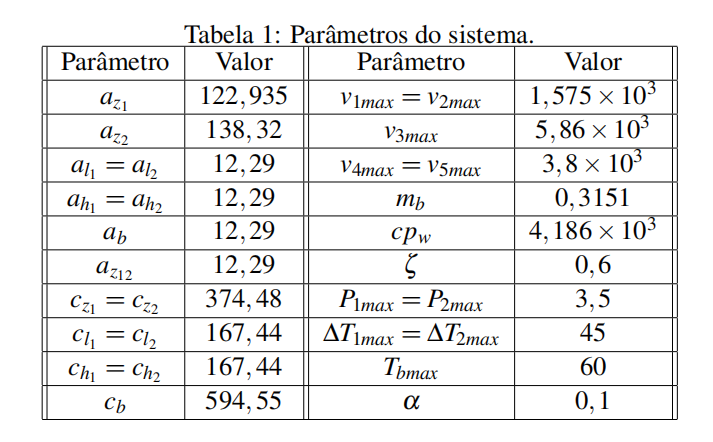

fonte: adaptada de [1] e [3];

az1ss = 122.935;
az2ss = 138.32;
al1ss = 12.29;
al2ss = 12.29;
ah1ss = 12.29;
ah2ss = 12.29;
abss = 12.29;
az12ss = 12.29;
cz1ss = 374.48;
cz2ss = 374.48;
cl1ss = 167.44;
cl2ss = 167.44;
ch1ss = 167.44;
ch2ss = 167.44;
cbss = 594.55;
v1maxss = 1.575e3;
v2maxss = 1.575e3;
v3maxss = 5.86e3;
v4maxss = 3.8e3;
v5maxss = 3.8e3;
mbss = 0.3151;
cpwss = 4.186e3;
qsiss = 0.6;
P1maxss = 3.5; 
P2maxss = 3.5;
deltaT1maxss = 45;
deltaT2maxss = 45;
Tbmaxss = 60;
alfass = 0.1;

Substituindo as informações da tabela 1 nas matrizes, temos:

% substitui os valores, mostra dfxd_at_ss
dfxd_at_ss = subs(dfxd,{Tb, Tl1, Th1, Tz1, Tl2, Th2, Tz2},{Tbss, Tl1ss, Th1ss, Tz1ss, Tl2ss, Th2ss, Tz2ss })

$$dfxd\_at\_ss = \left(\begin{array}{ccccccc} -\frac{\mathrm{ab}+2\,\mathrm{cpw}\,\mathrm{mb}+\frac{\mathrm{alfa}\,v_{3}\,\mathrm{v3max}}{\mathrm{Tbmax}}}{\mathrm{cb}} & \frac{\mathrm{cpw}\,\mathrm{mb}}{\mathrm{cb}} & 0 & 0 & \frac{\mathrm{cpw}\,\mathrm{mb}}{\mathrm{cb}} & 0 & 0\\ \frac{\mathrm{cpw}\,\mathrm{mb}}{{\mathrm{cl}}_{1}} & -\frac{{\mathrm{al}}_{1}+\mathrm{cpw}\,\mathrm{mb}}{{\mathrm{cl}}_{1}} & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & -\frac{{\mathrm{ah}}_{1}+\mathrm{qsi}\,v_{1}\,\mathrm{v1max}}{{\mathrm{ch}}_{1}} & \frac{\mathrm{qsi}\,v_{1}\,\mathrm{v1max}}{{\mathrm{ch}}_{1}} & 0 & 0 & 0\\ 0 & 0 & \frac{\mathrm{qsi}\,v_{1}\,\mathrm{v1max}}{{\mathrm{cz}}_{1}} & -\frac{{\mathrm{az}}_{1}+{\mathrm{az}}_{12}+\mathrm{qsi}\,v_{1}\,\mathrm{v1max}}{{\mathrm{cz}}_{1}} & 0 & 0 & \frac{{\mathrm{az}}_{12}}{{\mathrm{cz}}_{1}}\\ \frac{\mathrm{cpw}\,\mathrm{mb}}{{\mathrm{cl}}_{2}} & 0 & 0 & 0 & -\frac{{\mathrm{al}}_{2}+\mathrm{cpw}\,\mathrm{mb}}{{\mathrm{cl}}_{2}} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & -\frac{{\mathrm{ah}}_{2}+\mathrm{qsi}\,v_{2}\,\mathrm{v2max}}{{\mathrm{ch}}_{2}} & \frac{\mathrm{qsi}\,v_{2}\,\mathrm{v2max}}{{\mathrm{ch}}_{2}}\\ 0 & 0 & 0 & \frac{{\mathrm{az}}_{12}}{{\mathrm{cz}}_{2}} & 0 & \frac{\mathrm{qsi}\,v_{2}\,\mathrm{v2max}}{{\mathrm{cz}}_{2}} & -\frac{{\mathrm{az}}_{2}+{\mathrm{az}}_{12}+\mathrm{qsi}\,v_{2}\,\mathrm{v2max}}{{\mathrm{cz}}_{2}} \end{array}\right)$$

% pretty(dfxd_at_ss);               % - compatibilidade legada, sistemas sem "Live Editor"
dfud_at_ss = subs(dfud,{ v4, v1, v4, v2, v5 },{ v4ss, v1ss, v4ss, v2ss, v5ss })

$$dfud\_at\_ss = \left(\begin{array}{ccccc} 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

% pretty(dfud_at_ss);               % - compatibilidade legada, sistemas sem "Live Editor"
dfwd_at_ss = subs(dfwd,{ Te, Tp },{ Tess, Tpss })

$$dfwd\_at\_ss = \left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$

% pretty(dfwd_at_ss);               % - compatibilidade legada, sistemas sem "Live Editor"
dfyd_at_ss = subs(dfyd,{ Tb, Tz1, Tz2 },{ Tbss, Tz1ss, Tz2ss })

$$dfyd\_at\_ss = \left(\begin{array}{ccc} -\frac{\mathrm{ab}+2\,\mathrm{cpw}\,\mathrm{mb}+\frac{\mathrm{alfa}\,v_{3}\,\mathrm{v3max}}{\mathrm{Tbmax}}}{\mathrm{cb}} & 0 & 0\\ 0 & -\frac{{\mathrm{az}}_{1}+{\mathrm{az}}_{12}+\mathrm{qsi}\,v_{1}\,\mathrm{v1max}}{{\mathrm{cz}}_{1}} & \frac{{\mathrm{az}}_{12}}{{\mathrm{cz}}_{1}}\\ 0 & \frac{{\mathrm{az}}_{12}}{{\mathrm{cz}}_{2}} & -\frac{{\mathrm{az}}_{2}+{\mathrm{az}}_{12}+\mathrm{qsi}\,v_{2}\,\mathrm{v2max}}{{\mathrm{cz}}_{2}} \end{array}\right)$$

% pretty(dfyd_at_ss);               % - compatibilidade legada, sistemas sem "Live Editor" 

A tabela 2 apresenta os parâmetros para o ponto de equilíbrio:

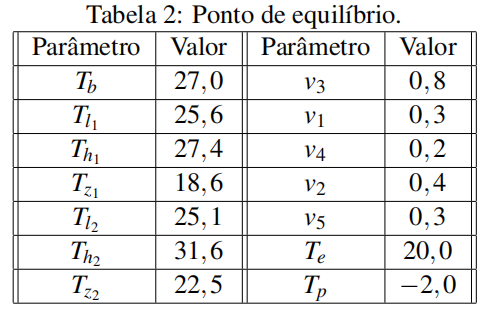

% Parâmetros do ponto de equilíbrio 
Tb = 27.0;
Tl1 = 25.6;
Th1 = 27.4;
Tz1 = 18.6;
Tl2 = 25.1;
Th2 = 31.6;
Tz2 = 22.5;
v3 = 0.8;
v1 = 0.3;
v4 = 0.2;
v2 = 0.4;
v5 = 0.3;
Te = 20.0;
Tp = -2.0;

Substituindo os parâmetros no ponto de equilíbrio, temos:

dfxd_nominal = subs(dfxd_at_ss, ...
    {sym('Tb'), sym('Tl1'),sym('Th1'),sym('Tz1'),sym('Tl2'),sym('Th2'),sym('Tz2'),...
     sym('v3'),sym('v1'),sym('v4'),sym('v2'),sym('v5'),sym('Te'),sym('Tp')}, ...
    { Tb, Tl1, Th1, Tz1, Tl2, Th2, Tz2, v3, v1, v4, v2, v5, Te, Tp })

$$dfxd\_nominal = \begin{array}{l} \left(\begin{array}{ccccccc} -\frac{\mathrm{ab}+2\,\mathrm{cpw}\,\mathrm{mb}+\frac{4\,\mathrm{alfa}\,\mathrm{v3max}}{5\,\mathrm{Tbmax}}}{\mathrm{cb}} & \frac{\mathrm{cpw}\,\mathrm{mb}}{\mathrm{cb}} & 0 & 0 & \frac{\mathrm{cpw}\,\mathrm{mb}}{\mathrm{cb}} & 0 & 0\\ \frac{\mathrm{cpw}\,\mathrm{mb}}{{\mathrm{cl}}_{1}} & -\frac{{\mathrm{al}}_{1}+\mathrm{cpw}\,\mathrm{mb}}{{\mathrm{cl}}_{1}} & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & -\frac{{\mathrm{ah}}_{1}+\sigma_{1}}{{\mathrm{ch}}_{1}} & \frac{3\,\mathrm{qsi}\,\mathrm{v1max}}{10\,{\mathrm{ch}}_{1}} & 0 & 0 & 0\\ 0 & 0 & \frac{3\,\mathrm{qsi}\,\mathrm{v1max}}{10\,{\mathrm{cz}}_{1}} & -\frac{{\mathrm{az}}_{1}+{\mathrm{az}}_{12}+\sigma_{1}}{{\mathrm{cz}}_{1}} & 0 & 0 & \frac{{\mathrm{az}}_{12}}{{\mathrm{cz}}_{1}}\\ \frac{\mathrm{cpw}\,\mathrm{mb}}{{\mathrm{cl}}_{2}} & 0 & 0 & 0 & -\frac{{\mathrm{al}}_{2}+\mathrm{cpw}\,\mathrm{mb}}{{\mathrm{cl}}_{2}} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & -\frac{{\mathrm{ah}}_{2}+\sigma_{2}}{{\mathrm{ch}}_{2}} & \frac{2\,\mathrm{qsi}\,\mathrm{v2max}}{5\,{\mathrm{ch}}_{2}}\\ 0 & 0 & 0 & \frac{{\mathrm{az}}_{12}}{{\mathrm{cz}}_{2}} & 0 & \frac{2\,\mathrm{qsi}\,\mathrm{v2max}}{5\,{\mathrm{cz}}_{2}} & -\frac{{\mathrm{az}}_{2}+{\mathrm{az}}_{12}+\sigma_{2}}{{\mathrm{cz}}_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{3\,\mathrm{qsi}\,\mathrm{v1max}}{10}\\ \sigma_{2}=\frac{2\,\mathrm{qsi}\,\mathrm{v2max}}{5} \end{array}$$


% pretty(dfxd_nominal)              % - compatibilidade legada, sistemas sem "Live Editor"
dfxd_nominal_val = eval(dfxd_nominal)

$$dfxd\_nominal\_val = \begin{array}{l} \left(\begin{array}{ccccccc} -\frac{\mathrm{ab}+2\,\mathrm{cpw}\,\mathrm{mb}+\frac{4\,\mathrm{alfa}\,\mathrm{v3max}}{5\,\mathrm{Tbmax}}}{\mathrm{cb}} & \frac{\mathrm{cpw}\,\mathrm{mb}}{\mathrm{cb}} & 0 & 0 & \frac{\mathrm{cpw}\,\mathrm{mb}}{\mathrm{cb}} & 0 & 0\\ \frac{\mathrm{cpw}\,\mathrm{mb}}{{\mathrm{cl}}_{1}} & -\frac{{\mathrm{al}}_{1}+\mathrm{cpw}\,\mathrm{mb}}{{\mathrm{cl}}_{1}} & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & -\frac{{\mathrm{ah}}_{1}+\sigma_{1}}{{\mathrm{ch}}_{1}} & \frac{3\,\mathrm{qsi}\,\mathrm{v1max}}{10\,{\mathrm{ch}}_{1}} & 0 & 0 & 0\\ 0 & 0 & \frac{3\,\mathrm{qsi}\,\mathrm{v1max}}{10\,{\mathrm{cz}}_{1}} & -\frac{{\mathrm{az}}_{1}+{\mathrm{az}}_{12}+\sigma_{1}}{{\mathrm{cz}}_{1}} & 0 & 0 & \frac{{\mathrm{az}}_{12}}{{\mathrm{cz}}_{1}}\\ \frac{\mathrm{cpw}\,\mathrm{mb}}{{\mathrm{cl}}_{2}} & 0 & 0 & 0 & -\frac{{\mathrm{al}}_{2}+\mathrm{cpw}\,\mathrm{mb}}{{\mathrm{cl}}_{2}} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & -\frac{{\mathrm{ah}}_{2}+\sigma_{2}}{{\mathrm{ch}}_{2}} & \frac{2\,\mathrm{qsi}\,\mathrm{v2max}}{5\,{\mathrm{ch}}_{2}}\\ 0 & 0 & 0 & \frac{{\mathrm{az}}_{12}}{{\mathrm{cz}}_{2}} & 0 & \frac{2\,\mathrm{qsi}\,\mathrm{v2max}}{5\,{\mathrm{cz}}_{2}} & -\frac{{\mathrm{az}}_{2}+{\mathrm{az}}_{12}+\sigma_{2}}{{\mathrm{cz}}_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{3\,\mathrm{qsi}\,\mathrm{v1max}}{10}\\ \sigma_{2}=\frac{2\,\mathrm{qsi}\,\mathrm{v2max}}{5} \end{array}$$


dfud_nominal = subs(dfud_at_ss, ...
    {sym('Tb'), sym('Tl1'),sym('Th1'),sym('Tz1'),sym('Tl2'),sym('Th2'),sym('Tz2'),...
     sym('v3'),sym('v1'),sym('v4'),sym('v2'),sym('v5'),sym('Te'),sym('Tp')}, ...
    { Tb, Tl1, Th1, Tz1, Tl2, Th2, Tz2, v3, v1, v4, v2, v5, Te, Tp })

$$dfud\_nominal = \left(\begin{array}{ccccc} 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$


% pretty(dfud_nominal)              % - compatibilidade legada, sistemas sem "Live Editor"
dfud_nominal_val = eval(dfud_nominal)

dfud_nominal_val =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0



dfwd_nominal = subs(dfwd_at_ss, ...
    {sym('Tb'), sym('Tl1'),sym('Th1'),sym('Tz1'),sym('Tl2'),sym('Th2'),sym('Tz2'),...
     sym('v3'),sym('v1'),sym('v4'),sym('v2'),sym('v5'),sym('Te'),sym('Tp')}, ...
    { Tb, Tl1, Th1, Tz1, Tl2, Th2, Tz2, v3, v1, v4, v2, v5, Te, Tp })

$$dfwd\_nominal = \left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$


% pretty(dfwd_nominal)              % - compatibilidade legada, sistemas sem "Live Editor"
dfwd_nominal_val = eval(dfwd_nominal)

dfwd_nominal_val =      0     0
     0     0



dfyd_nominal = subs(dfyd_at_ss, ...
    {sym('Tb'), sym('Tl1'),sym('Th1'),sym('Tz1'),sym('Tl2'),sym('Th2'),sym('Tz2'),...
     sym('v3'),sym('v1'),sym('v4'),sym('v2'),sym('v5'),sym('Te'),sym('Tp')}, ...
    { Tb, Tl1, Th1, Tz1, Tl2, Th2, Tz2, v3, v1, v4, v2, v5, Te, Tp })

$$dfyd\_nominal = \left(\begin{array}{ccc} -\frac{\mathrm{ab}+2\,\mathrm{cpw}\,\mathrm{mb}+\frac{4\,\mathrm{alfa}\,\mathrm{v3max}}{5\,\mathrm{Tbmax}}}{\mathrm{cb}} & 0 & 0\\ 0 & -\frac{{\mathrm{az}}_{1}+{\mathrm{az}}_{12}+\frac{3\,\mathrm{qsi}\,\mathrm{v1max}}{10}}{{\mathrm{cz}}_{1}} & \frac{{\mathrm{az}}_{12}}{{\mathrm{cz}}_{1}}\\ 0 & \frac{{\mathrm{az}}_{12}}{{\mathrm{cz}}_{2}} & -\frac{{\mathrm{az}}_{2}+{\mathrm{az}}_{12}+\frac{2\,\mathrm{qsi}\,\mathrm{v2max}}{5}}{{\mathrm{cz}}_{2}} \end{array}\right)$$


% pretty(dfyd_nominal)              % - compatibilidade legada, sistemas sem "Live Editor"
dfyd_nominal_val = eval(dfyd_nominal)

$$dfyd\_nominal\_val = \left(\begin{array}{ccc} -\frac{\mathrm{ab}+2\,\mathrm{cpw}\,\mathrm{mb}+\frac{4\,\mathrm{alfa}\,\mathrm{v3max}}{5\,\mathrm{Tbmax}}}{\mathrm{cb}} & 0 & 0\\ 0 & -\frac{{\mathrm{az}}_{1}+{\mathrm{az}}_{12}+\frac{3\,\mathrm{qsi}\,\mathrm{v1max}}{10}}{{\mathrm{cz}}_{1}} & \frac{{\mathrm{az}}_{12}}{{\mathrm{cz}}_{1}}\\ 0 & \frac{{\mathrm{az}}_{12}}{{\mathrm{cz}}_{2}} & -\frac{{\mathrm{az}}_{2}+{\mathrm{az}}_{12}+\frac{2\,\mathrm{qsi}\,\mathrm{v2max}}{5}}{{\mathrm{cz}}_{2}} \end{array}\right)$$

### Referências:

[1] M. Zaheer-Uddin, RV Patel, and SAK Al-Assadi. Design of decentralized robust controllers for multizone space heating systems. *IEEE Transactions on Control Systems Technology*, 1(4):246–261, 2002. 

[2] Saboksayr, Hossein. Neural network based decentralized control of an MZSH system*. Dissertação de Mestrado, Concordia University*, 1995. Disponível em: [https://spectrum.library.concordia.ca/id/eprint/3761/1/MM05135.pdf.](https://spectrum.library.concordia.ca/id/eprint/3761/1/MM05135.pdf.) Acesso em: out. 22.

[3] Material didático disponibilizado pelos docentes.